# Brood Locs analysis

load('Data\BroodLocs.mat','BroodLocs')
UseNests2 = [3:8 11:13 15:18 20 22 25:29];

%% analyze
PercentType2 = zeros(29,1);
for k=UseNests2
    PercentType2(k) = sum(BroodLocs.tag==k & BroodLocs.SType==2)./sum(BroodLocs.tag==k);
end

MeanPercentByNest = mean(PercentType2(UseNests2));
PercentType = zeros(3,1);
for i=1:3
    PercentType(i) = sum(BroodLocs.SType==i)./height(BroodLocs);
end

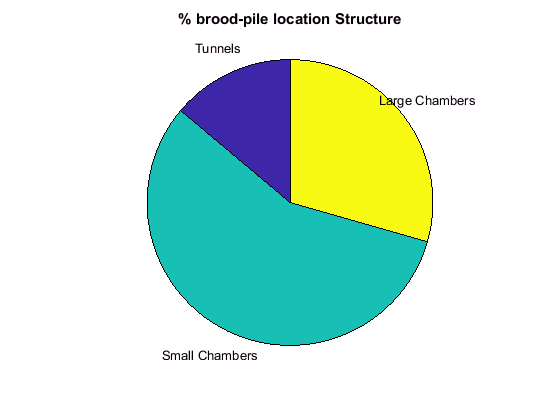

labels = {'Tunnels','Small Chambers','Large Chambers'};
pie(PercentType,labels)
title('% brood-pile location Structure') 